clearvars; close('all');
% GNSS headng
% compass = 'GNSS';
% 
% load("data\CS_GNSS.mat");region='Celtic Sea';
% load("data\RT_GNSS.mat"); region='Rockall Trough';

% sig compasss
compass = 'signature';
%load("data\CS_SIG.mat"); region='Celtic Sea';
load("data\RT_SIG.mat");region='Rockall Trough';

% sig compasss
% compass = 'bottomtrack';
% load("data\IN_BT.mat"); region='Inshore';
% load("data\RT_SIG.mat");region='Rockall Trough';

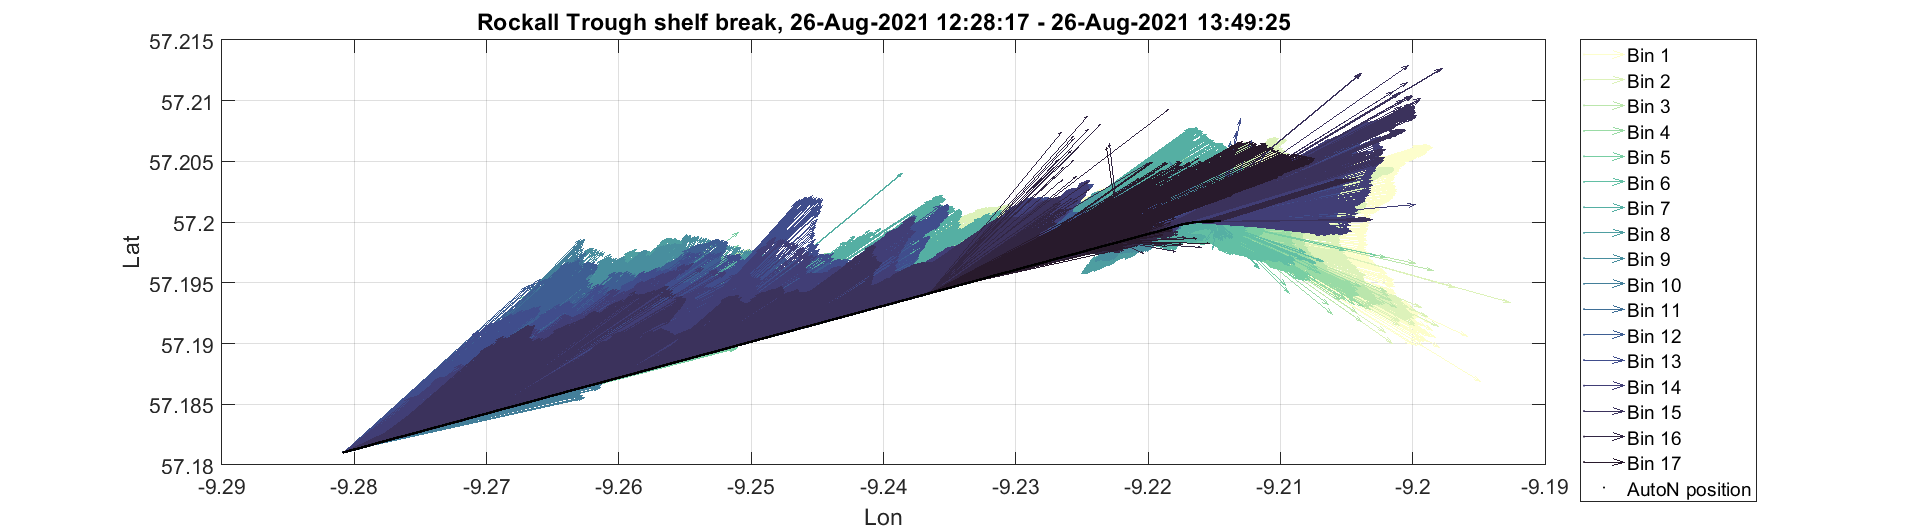

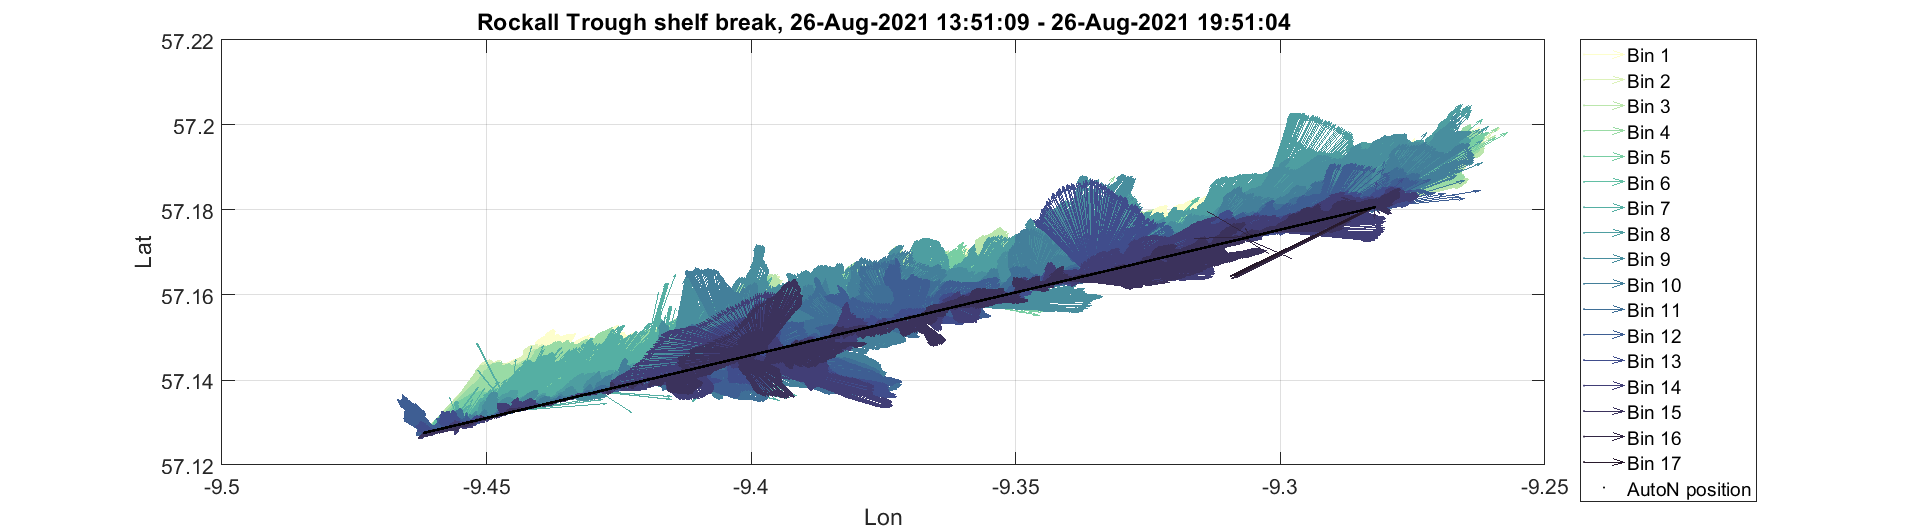

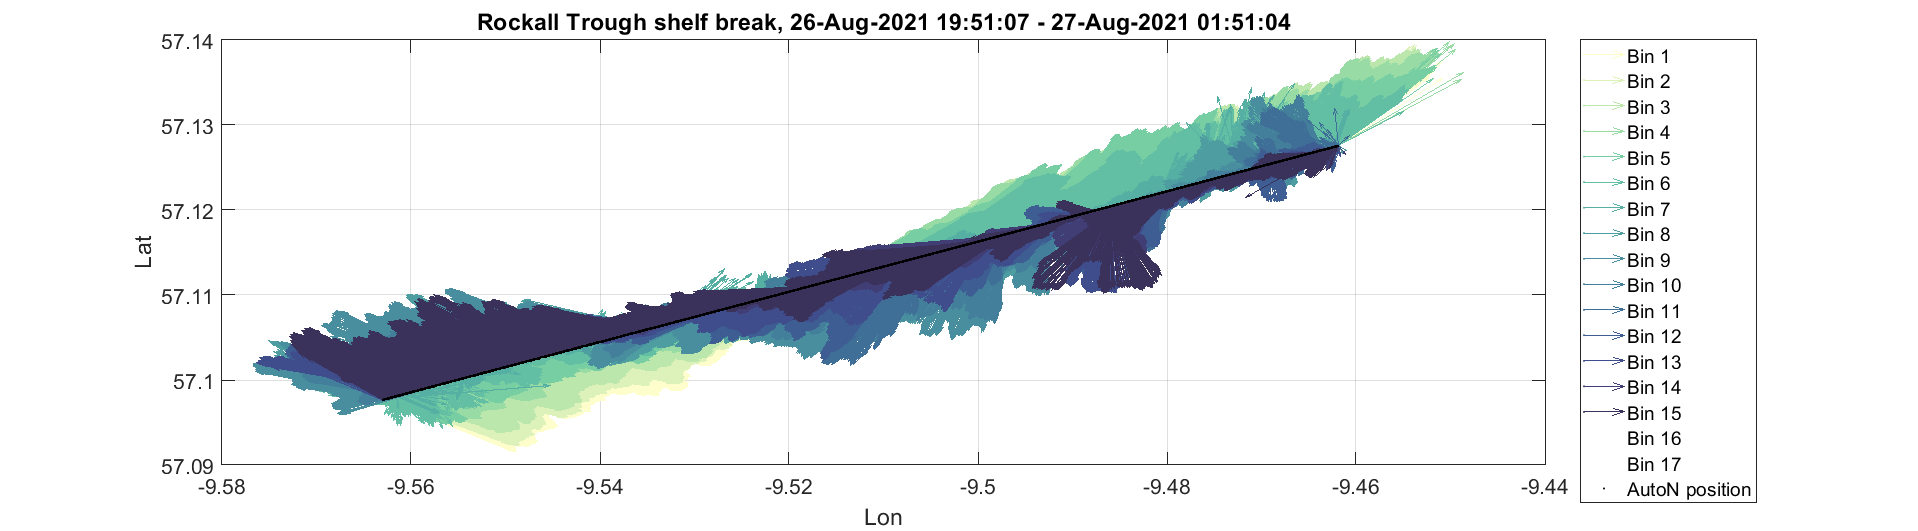

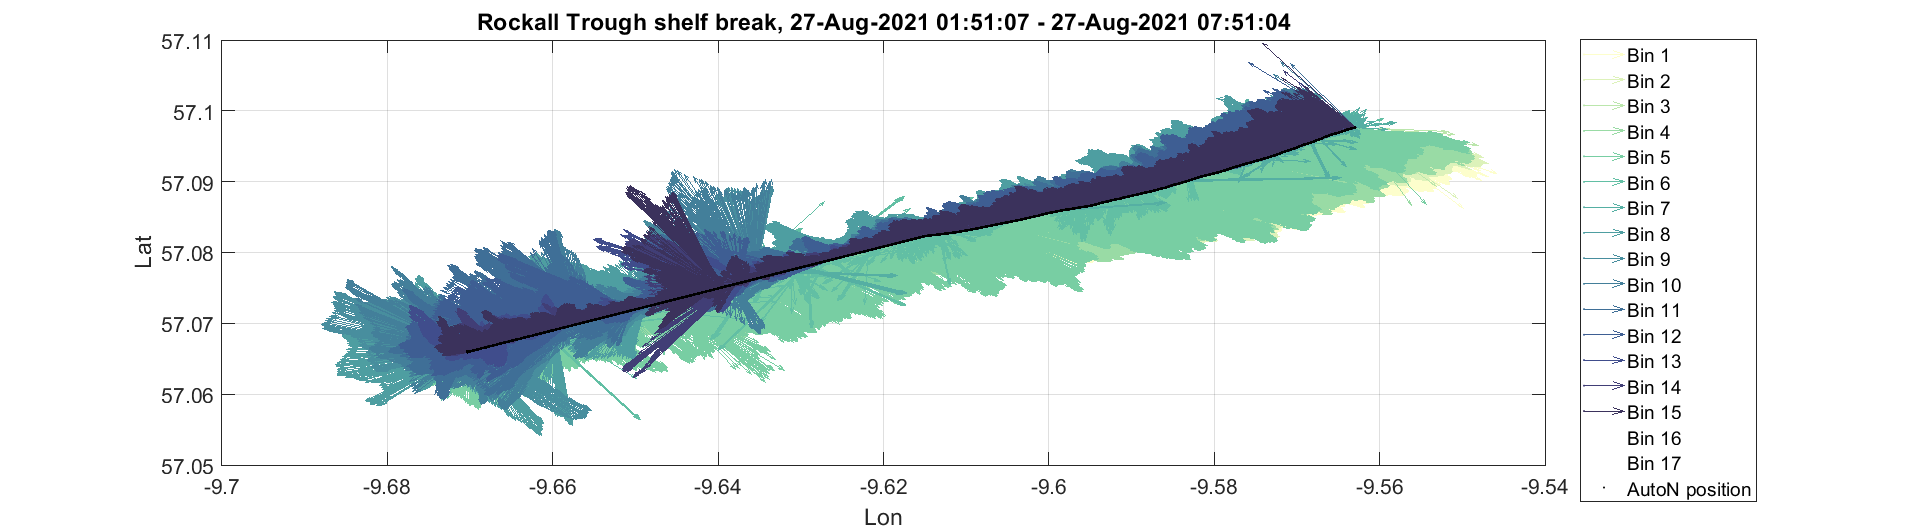

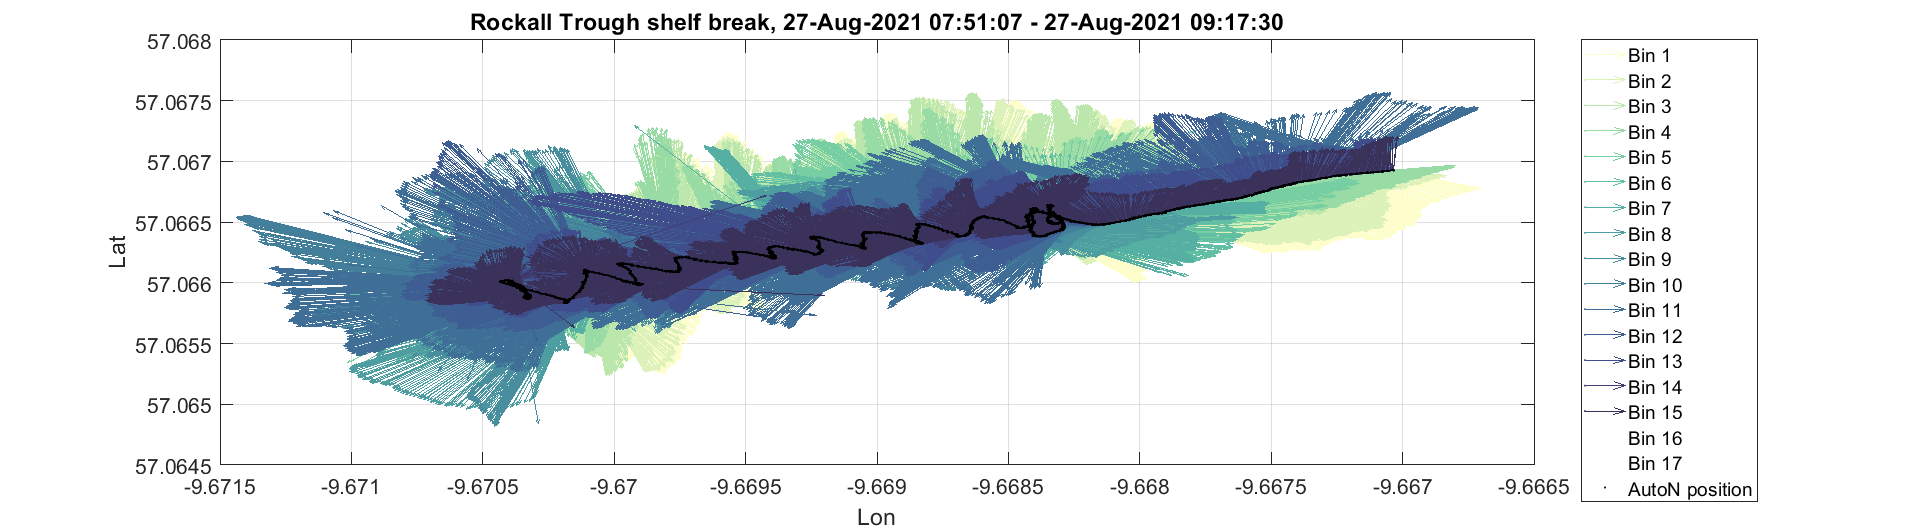

clrs=cmocean('Deep',17);

for mm = 1:numel(WatStruct)

   figure('Renderer', 'painters', 'Position', [10 20 6000 2400])
   for ii = 1:17
        X=NavStruct(mm).long_deg; x=X';
        x=repmat(x,17,1);
        Y=NavStruct(mm).lat_deg;y=Y';
        y=repmat(y,17,1);
        u=WatStruct(mm).vEast_ms;
        v=WatStruct(mm).vNorth_ms;
%         Q=quivers(x,y,u,v,12,4,'m/s',[clrs(ii,:) 0.5]);

        Q1=quiver(x(ii,:),y(ii,:),u(ii,:),v(ii,:),...
            'AutoScaleFactor',24,...
            'LineWidth',0.5,...
            'MaxHeadSize',0.02,...
            "Color",[clrs(ii,:) 0.7],...
            'Marker','.',...
            'MarkerFaceColor','k');
        legstr{ii}=['Bin ' num2str(ii)];
        hold on
   end
%     ug=NavStruct(mm).gpsVeast; vg=NavStruct(mm).gpsVnorth;
%     q=quiver(X,Y,ug,vg,'AutoScaleFactor',12,'LineStyle','-','LineWidth',0.02,'Color','r');
    
    p1=plot(X,Y,'k.');
    legstr{ii+1}='GPS vector';
    legstr{ii+1}='AutoN position';
    grid on
    xlabel('Lon');
    ylabel('Lat');
    title([region ' shelf break, '  datestr(NavStruct(mm).timestamp(1)) ' - ' datestr(NavStruct(mm).timestamp(end))]) ;
    legend(legstr,'Location',"bestoutside");
    set(gca,'FontSize',16);
    print(gcf,'-dpng',['figures/' region '_vec_' compass '_' num2str(mm)]) ;  
end

% figure('Renderer', 'painters', 'Position', [10 20 1200 400])
% m_proj('azimuthal equal-area','latitude',55,'long',-15,'radius',20,'rectbox','on');m_coast('color','k');m_grid('linewi',2,'tickdir','out');
% m_quiver(X,Y,u,v);

% Q2=quivers(X,Y,u,v,2,1,'m/s','k');